Let's consider the pendulum governed by the following second-order ODE:

$\textrm{ma}=\textrm{ml}\ddot{\theta \;} =-\textrm{mgsin}\theta \;$.

In this equation, $\theta =0$ represents the pendulum hanging straight down (aligned perfectly with gravity). At small angles, we can approximate $\sin \theta \approx \theta \;$, so we have

$\ddot{\;\theta \;} =-\frac{g}{l}\theta \;$.

But this is a second-order ODE, so we cannot directly apply our time-stepping methods to it. We introduce the variable $\omega =\dot{\theta \;}$ to arrive at the following system of first-order ODEs:

$\left\lbrack \begin{array}{c}
\dot{\theta \;} \\
\dot{\omega \;} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\omega \;\\
-\frac{g}{l}\theta \;
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
0 & 1\\
-\frac{g}{l} & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\theta \\
\omega \;
\end{array}\right\rbrack$.

This is a linear system. Now, let's suppose we pull the pendulum to $\theta_0 =\frac{\pi }{4}$ at $t=0$ and release it from rest (i.e., $\omega_{0\;} =0$). The exact solution to this initial value problem is

$\theta(t) = \frac{\pi}4 \cos\left(\sqrt{\frac gl}t\right)$.

We take $g=9\ldotp 8\;\frac{\mathrm{m}}{{\mathrm{s}}^{2\;} }$ and $l=0\ldotp 10$ m and plot the true solution in the interval [0,T] where T = 5:

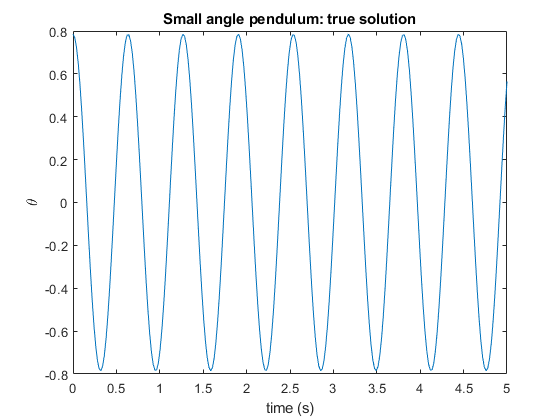

% problem parameters
g = 9.8; % [m/s^2]
l = 0.1; % [m]

t_plot = linspace(0,5,250); % make uniform grid on [0, 10] with 200 points
figure(1); clf 
plot(t_plot, pi/4*cos(sqrt(g/l)*t_plot))
xlabel('time (s)')
ylabel('\theta')
title('Small angle pendulum: true solution')

Now let's use forward Euler to approximate the solution for $l=0\ldotp 10$ m and $g=9\ldotp 8\;\frac{\mathrm{m}}{{\mathrm{s}}^{2\;} }$, and compare to the true solution:

% define ODE dynamics f for u = [theta; omega]
f = @(t,u) [u(2); -g/l*u(1)];

% define initial condition
theta_0 = pi/4;
omega_0 = 0;
uFE_0     = [theta_0; omega_0];

% set up time discretization
T = 5;             % [s] final time 
dt = 0.1; % [s] timestep size
t = dt:dt:T;        % discrete times
K = length(t);      % number of time steps
                  
% forward Euler
tic                                 % start timer
uFE = zeros(2,K);                   % pre-allocate space for all approximate u
uFE(:,1) = uFE_0 + dt*f(0,uFE_0);   % take first time step from initial condition
for i = 2:K                         % loop thru all remaining time steps and update
    uFE(:,i) = uFE(:,i-1) + dt*f(t(i-1),uFE(:,i-1));  % fwd Euler update
end
toc % end timer and print

Elapsed time is 0.007030 seconds.



% compute error in theta(t) at t = T
final_error = abs(pi/4*cos(sqrt(g/l)*T) - uFE(1,end))

final_error = 5.1216e+06

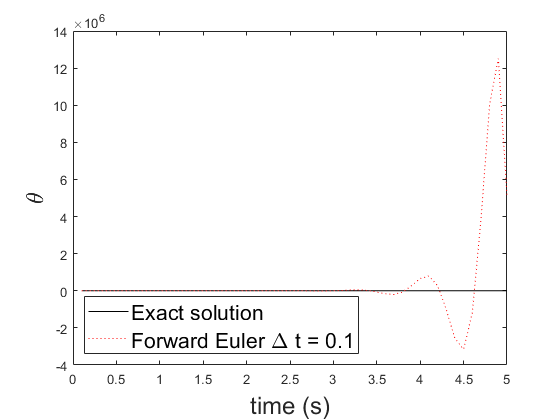


% plot theta vs time
figure(2); clf
plot(t,pi/4*cos(sqrt(g/l)*t),'k')   % plt exact solution vs. t. the 'k' argument sets the color to black
hold on                             % don't erase my current plot while adding new ones
plot(t,uFE(1,:),'r:')               % plt forward Euler solution vs. t in dotted red line
xlabel('time (s)','FontSize',18)
ylabel('\theta','FontSize',18)
legend('Exact solution',['Forward Euler \Delta t = ',num2str(dt)],...
    'Location','SouthWest','FontSize',16)

#### In-class activity: write your answers below each prompt and upload to Canvas when you are done (one upload per group is fine).

#### (0) Introduce yourselves to each other in the breakout room - name, optional pronouns, year, major, and house is good. Please list full names of all students in your group: 

#### Kyle McGraw, Dallas Taylor, Spencer Schneider

#### (1) discuss as a group/convince yourself that lines 25-33 in the above code do indeed implement the Forward Euler time-stepping scheme we presented in class. No response needed for this question.

#### We are convinced!

#### (2) Note that you can vary the timestep size, $\Delta \;t$, using the dropdown menu in line 21 above. When you select an option it should automatically re-run the script and generate a new output in the panel on your right. Change up the timestep size and answer the following questions in complete sentences:

####     (a) How does the error at the final time change as the timestep is decreased from $\Delta \;t=0\ldotp 001={10}^{-3}$ to $\Delta \;t=0\ldotp 00001={10}^{-5}$? What would you expect the error to be if you decreased further to $\Delta \;t={10}^{-6}$?

#### The error decreases from 0.1557 to 0.0014 as we decrease the size of the timestep. We would expect the error to converge further to zero if we decreased the timestep.

####     (b) How does the error at the final time change as you increase the timestep to $\Delta \;t=0\ldotp 01,0\ldotp 1$? What do you observe in the plot of the forward Euler approximation over time? What do you think is happening here?

#### The final error increases to 4.8207 and 5.1216*10^6, respectively, as we increase the timestep. We observe that the plot of the forward Euler goes crazy and diverges from the exact solution as the time increases. We think that the error compounds and causes the approximation to go further away from the solution.

####     (c) How does the number of timesteps, K, change as the timestep size, $\Delta \;t$, changes? How does the number of times we call the function $\mathbf{f}\left(t,\mathit{\mathbf{u}}\right)$ change as a result? 

#### As $\Delta \;t$ increases, the number of timesteps decreases, and therefore the number of times we call the function $\mathbf{f}\left(t,\mathit{\mathbf{u}}\right)$ decreases. 

####     (d) In real-world applications, evaluating the function $\mathbf{f}$ is often the most computationally expensive (time-consuming) part of the simulation. Knowing this, summarize in 1-2 sentences how computational cost and accuracy change with $\Delta \;t$.

As $\Delta \;t$ increases, the computational cost decreases since the number of timesteps decreases, but the accuracy also might decrease because of the larger, less accurate steps.